# **Práctica 0**

**Nombre:  Pablo **

**Apellidos: Mendieta Ruiz **

**Fecha: 03 / 10 / 2023**

## **Enunciado del problema**

Supongamos que una taza de café, inicialmente a una temperatura de 65ºC se coloca en una habitación que se mantiene a una temperatura constante de 20ºC. Después de 1 minuto, el café se ha enfriado a 60ºC. La ley de enfriamiento de Newton establece que la variación de la temperatura de un objeto es proporcional a la diferencia entre su propia temperatura y la temperatura ambiente (es decir, la temperatura de su entorno). 

## Se pide

Calcular la temperatura del café depués de 15 minutos en la habitación. 

**a)** Definir la ecuación en diferencias que representa el proceso de enfriamiento del café tomando como guía la ley de enfriamiento de Newton. 

A tener el cuenta el nombre de las siguientes variables:

- T(n) = temperatura en el minuto n.

- k = constante de proporcionalidad.

- a = temperatura ambiente (en este caso constante = 20º).

**b) **Determinar el valor de la constante de proporcionalidad k teniendo en cuenta la información del problema sobre los cambios en el primer minuto. 

**c) **Realizar el diagrama de flujo que representa la simulación del proceso de enfriamiento del café.

**d)** Realizar un programa en Matlab que devuelva:

- Temperatura del café después de 15 minutos en la habitación. 

- Un gráfico de la evolución de la temperatura del café durante los 15 minutos que el café permanece en la habitación. 

**e) **Estudiar la estabilidad del sistema y, en caso de que sea estable, calcular el punto de equilibrio.

## Solución a)

$\Delta$Tn =(T1 - a) k * Tn+1 

## Solución b)

Tinicio = 65; % temperatura inicial 
Tfin = 60; % temperatura final 
a = 20; % Temperatura ambiente

k = - ( Tinicio - Tfin) / (Tinicio - a); % Constante de proporcionalidad

fprintf('La constante de proporcionalidad es : %.4f', k)

La constante de proporcionalidad es : -0.1111

## Solución c)

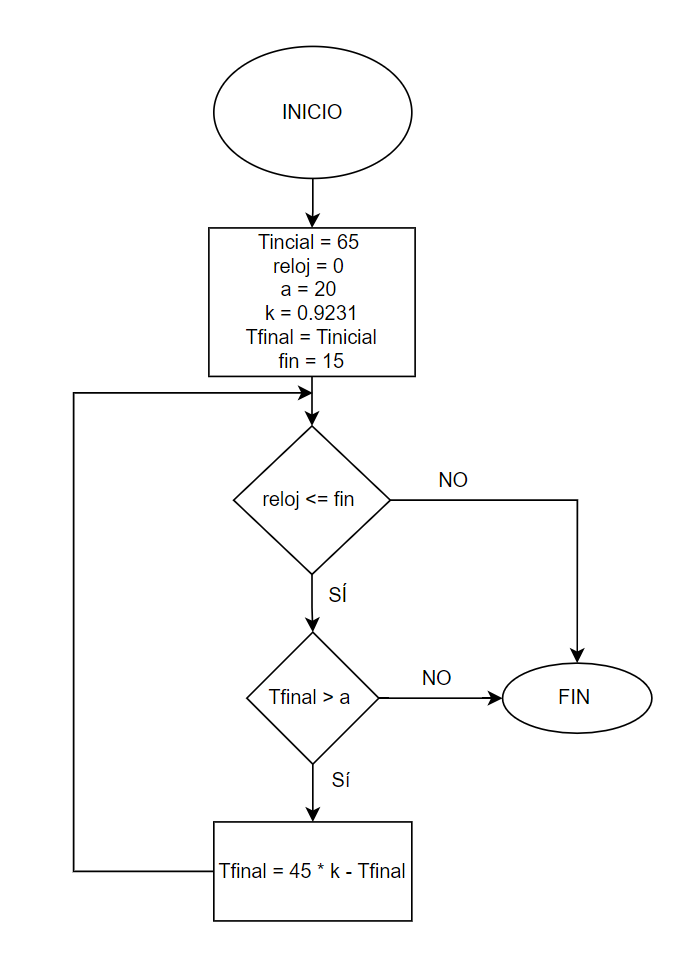

## Solución d)

reloj = 1 ; 
fin = 15;
Tfin = Tinicio;

temperatura = (Tinicio);
i = 1;
% Rutina de parada 
while reloj <= fin 

    % Rutina de tiempo
    reloj = reloj + 1;

    if Tfin > a

    % Rutina de evento 
        Tfin = (Tinicio - a) * k + Tfin;
        Tinicio = Tfin;
        temperatura(i) = Tfin;
        i = i + 1;
    else
        fprintf('La temperta es igual a la temperatura ambiente')
        break
    end

end
fprintf('La temperatura en el minuto 15 es : %.4f', temperatura(i-1))

La temperatura en el minuto 15 es : 27.6900

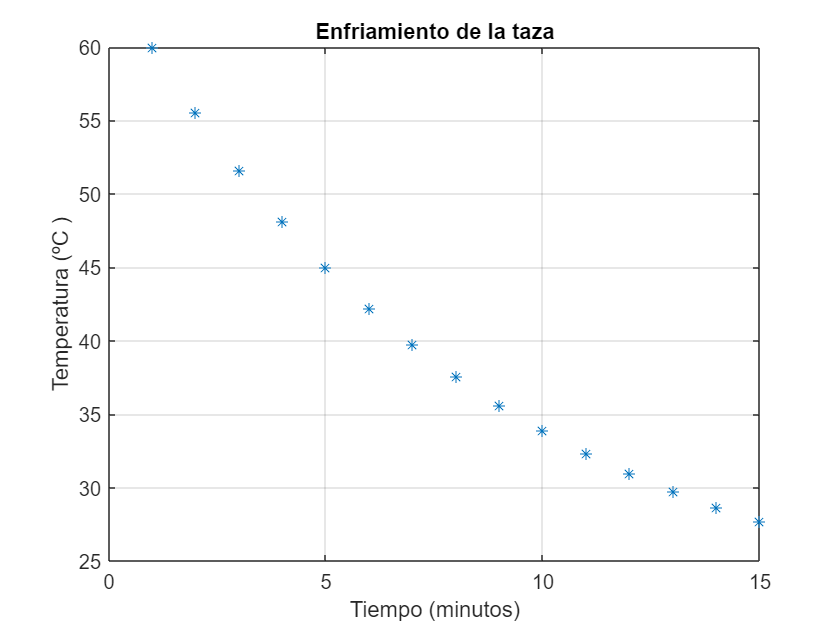

plot(1:15,temperatura,'*')
grid on 
title ('Enfriamiento de la taza');
xlabel( 'Tiempo (minutos)');
ylabel('Temperatura (ºC )');

## Solución e)

% Rutina de parada 
fin = inf;
while reloj <= fin 

    % Rutina de tiempo
    reloj = reloj + 1;

    if Tfin > a

    % Rutina de evento 
        Tfin = (Tinicio - a) * k + Tfin;
        Tinicio = Tfin;
        temperatura(i) = Tfin;
        i = i + 1;
    else
        fprintf('La temperta es igual a la temperatura ambiente')
        break
    end
    T1 = temperatura(i-2);
    T1 = round(T1, 4);
    T2 = temperatura(i-1);
    T2 = round(T2, 4);
    if T1 == T2
        fprintf('Estabilidad del sistema: %.4f', T1);
        break
    end

end

Estabilidad del sistema: 20.0006

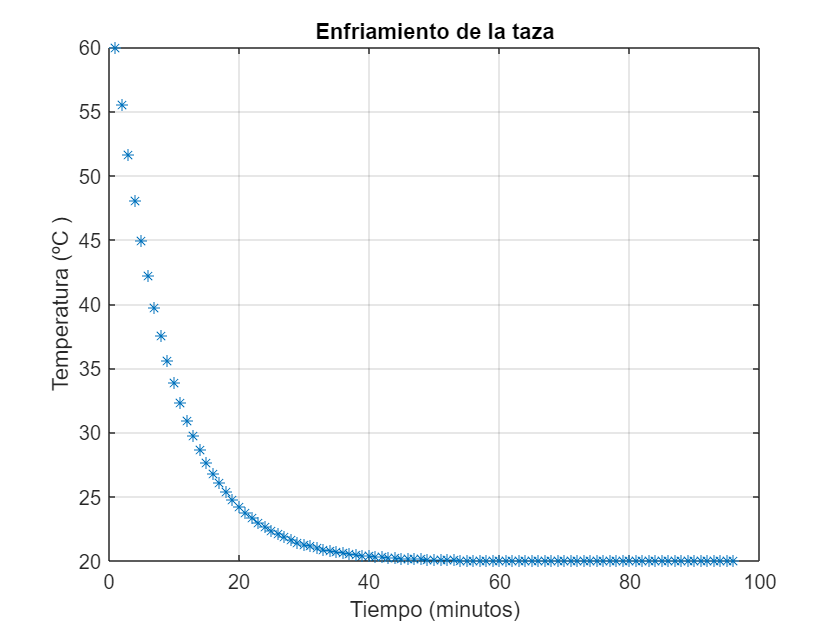


plot(1:(i-1),temperatura,'*')
grid on 
title ('Enfriamiento de la taza');
xlabel( 'Tiempo (minutos)');
ylabel('Temperatura (ºC )');


fprintf(['Como vemos en la gráfica la estabilidad del sistema es ' ...
    '( punto de equilibrio ): %.4f ºC y llegamos en el minuto %d'], T1, i)

Como vemos en la gráfica la estabilidad del sistema es ( punto de equilibrio ): 20.0006 ºC y llegamos en el minuto 97